# Edge Enhancement Algorithm Based on the Wavelet Transform for Automatic Edge Detection in SAR Images

Prepared for Dr. Oleg Michailovich

ECE 417 Image Processing Project

Prepared by: Awn Duqoum, Sasha Hall, Maya Deen

## 1. Problem Formulation

Satellite synthetic aperture radar (SAR) images are high-resolution images of large regions of the Earth. Radar images cannot be interpreted conventionally as their data is very heterogeneous, and must undergo pre-processing in order to extract meaningful interpretations from the data. This process is made more complex by the presence of speckle in SAR images, which is a multiplicative noise-like pattern. The problem presented in this report is edge detection in SAR images. 

## 2. Proposed Solution

The proposed solution is based on the algorithm from the paper *Edge Enhancement Algorithm Based on the Wavelet Transform for Automatic Edge Detection in SAR Images. *It is composed of two parts: edge enhancement followed by edge detection. 

The following is a high level overview of the edge enhancement algorithm:

- Take the logarithm of the input signal

- Take the 2D stationary wavelet transform, which produces 4 frequency bands: horizontal (H), vertical (V), diagonal (D), and the low-pass-filtered component of the image

- For each subband, take the absolute value and normalize to the maximum 

- Take the pointwise maximum of all three subbands {H, V, D}

- Combine the intermediate pointwise maxima through pointwise multiplication

After the edges of the image have been enhanced, a decision step is required to separate the input image into two classes: edges and no edges. In this solution a geodeic active contour algorithm is used to create a continuous, closed contour while minimizing noise and artifacts appearing in the output.

The algorithm for the geodesic active contour is:

- ?????

## 3. Data Sources

The simulated data source is constructed from a speckle matrix with an embedded square of increased intensity in the middle. The intensity of the square was changed by multiplying it with a constant value, m.

The speckle matrix is composed of random real and imaginary parts for elements. The randomly generated components are normally distributed with zero mean and variance equl to 0.5.

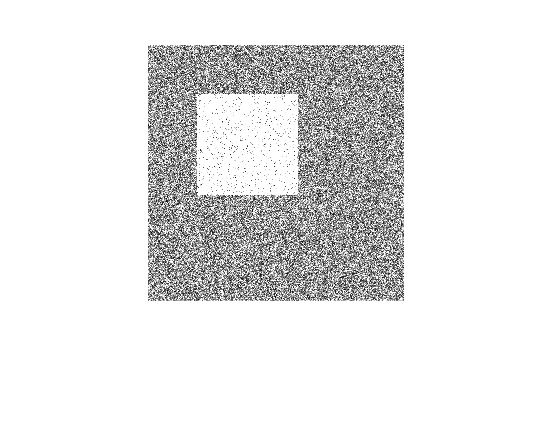

img_size = [256, 256];
m = 5; 

% Create the speckle pattern 
A = 0.5*randn(img_size) + 1i*0.5*randn(img_size);
A = abs(A);

% Create our superimposeed white squre object
A(50:150, 50:150) = m * A(50:150, 50:150);

imshow(A)

## 4. Solution

**2D Wavelet Transform of Mother Wavelet**

The wavelet transform is expressed as:


$$W_f \left(u,s\right)=\text{ }\int_{−\infty }^{\infty } f\left(x\right)\frac{1}{\sqrt{s}}\psi ∗\left(\frac{x−u}{s}\right)dx$$


The Haar wavelet was chosen as the mother wavelet for its linear phase, single vanishing moment and small number of coefficients. It is expressed as:


$$\psi \left(t\right)=\text{ }\left\lbrace \begin{array}{c}
1 & 0\le t<\frac{1}{2}\\
−1 & \frac{1}{2}\le t<1\\
0 & otherwise
\end{array}\right.$$


Therefore the wavelet transform becomes:


$$W_f \left(u,s\right)=\text{ }\frac{1}{\sqrt{s}}\int_u^{\frac{s}{2}+u} f\left(x\right)dx−\text{ }\frac{1}{\sqrt{s}}\int_{\frac{s}{2}+u}^{s+u} f\left(x\right)dx$$


By taking the logarithm of the original signal, the multiplicative speckle can be can be transformed to additive, signal independent noise with an approximately Gaussian distribution:


$$f(\tau) = \mbox{log}(\sigma(\tau)n(\tau)) = \mbox{log}(\sigma(\tau)) + \mbox{log}(n(\tau))$$


where \sigma is the useful information and n is the multiplicative noise component.

Substituting the logarithm of the signal into the wavelet transform:


$$W_f \left(u,s\right)=\text{ }\frac{1}{\sqrt{s}}\left\lbrack \int_u^{\frac{s}{2}+u} \left\lbrack log\left(\sigma \left(x\right)\right)+log\left(n\left(x\right)\right)\right\rbrack \text{dx}\right\rbrack −\text{ }\frac{1}{\sqrt{s}}\int_{\frac{s}{2}+u}^{s+u} \left\lbrack log\left(\sigma \left(x\right)\right)+log\left(n\left(x\right)\right)\right\rbrack \text{dx}$$



$$W_f \left(u,s\right)=\text{ }\frac{1}{\sqrt{s}}\left\lbrack \int_u^{\frac{s}{2}+u} \log \left(\sigma \left(x\right)\right)dx−\int_{\frac{s}{2}+u}^{s+u} \log \left(\sigma \left(x\right)\right)dx\right\rbrack +\frac{1}{\sqrt{s}}\left\lbrack \int_u^{\frac{s}{2}+u} \log \left(n\left(x\right)\right)dx−\int_{\frac{s}{2}+u}^{s+u} \log \left(n\left(x\right)\right)dx\right\rbrack$$


If there is a discontinuity between the two intervals, the difference between the noise ///

## 5. Results Visualization

## 6. Analysis & Conclusions

//Have you been able to reproduce the results reported in the original paper? Did the algorithm behave in a predictable way, i.e., as described by the authors? Do you own conclusions support those made by the  authors? What are the drawbacks (if any) of the proposed solution?)

## 7. Custom Algorithm Implementation Files

No custom source files/functions were used in addition to the code here.